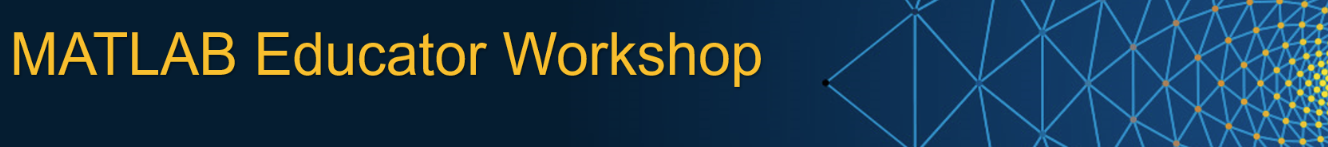

# Demo: Solving a location optimization problem

## Problem Statement

- The goal is to minimize the total distance between the factory and the stores, thereby reducing battery consumption during shipping.

- Assuming the transportation is using drone and no obstacle (tree, buildings, etc) existed, **where is the best location (in X-Y coordinate) for the new factory?**

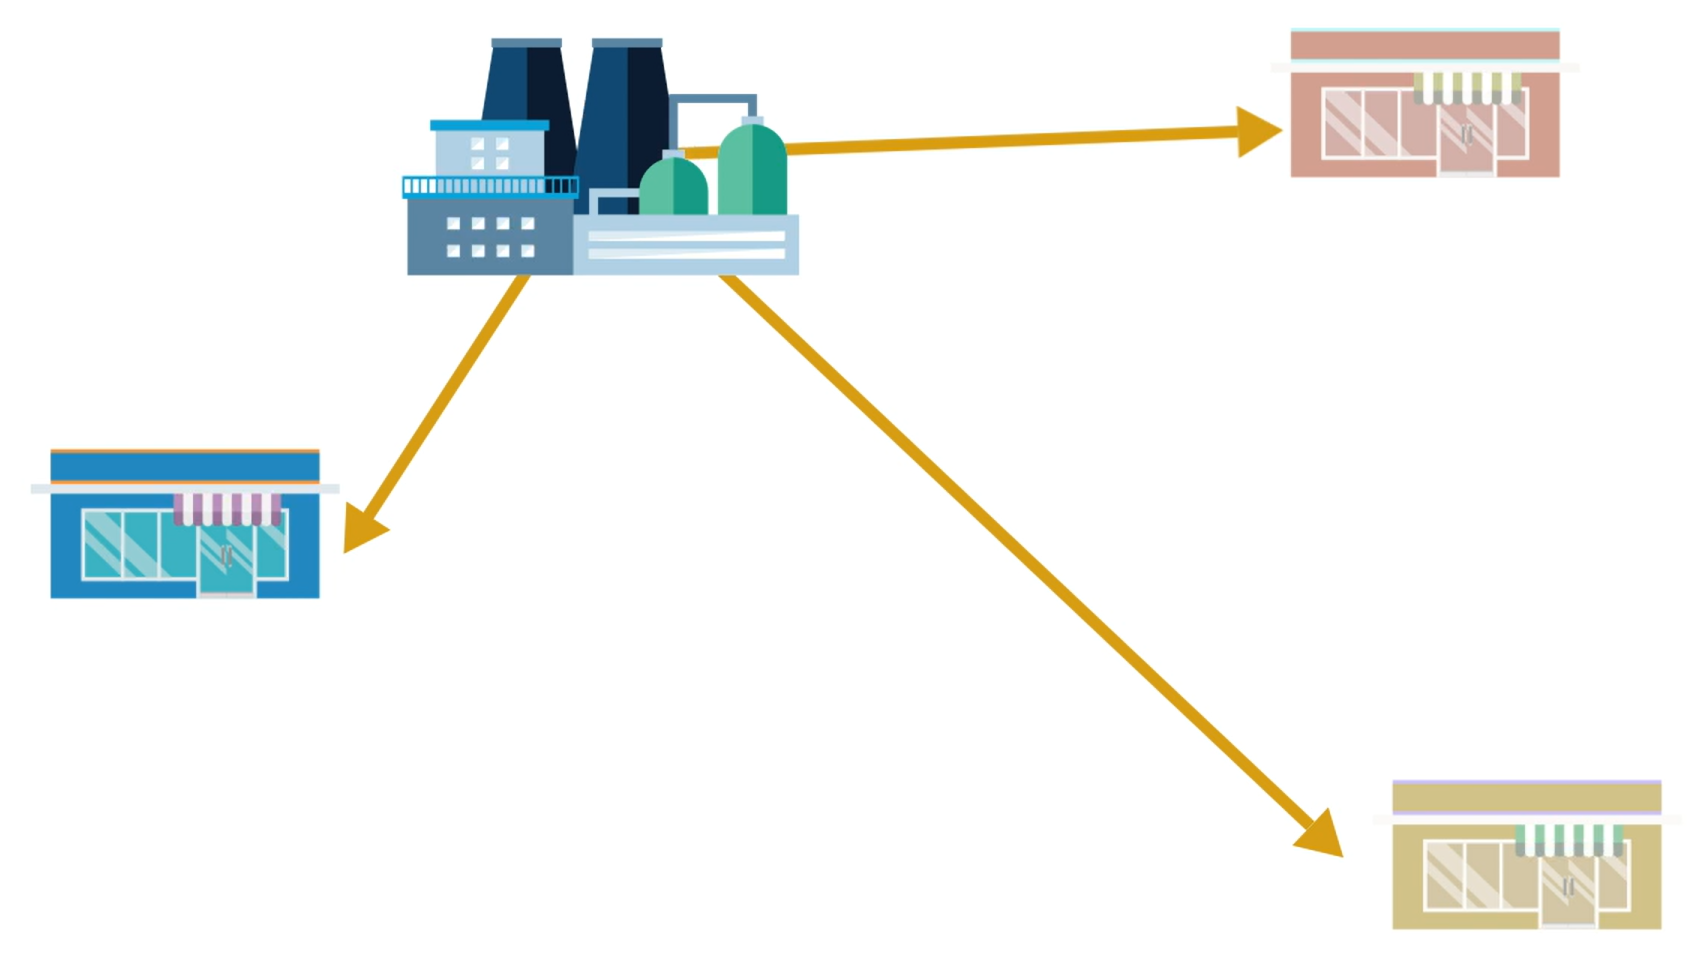

## Visualization of the Locations

**Notes**: Show live script, live task, control task

A company has existing 3 stores. Here's the coordinates:

%             (               x    ,                y    )
blueStore   = [1, 4];
redStore    = [10, 12];
yellowStore = [8, 1.2];

Where zero point is top-left of the map.

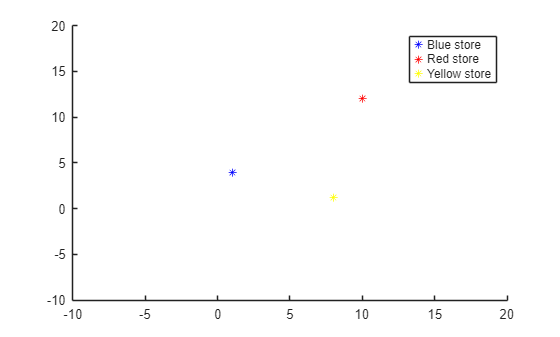

renderStoresPlot(blueStore, redStore, yellowStore);

Now, we want to build a new factory which close enough to those stores.

## Requirements

### Goal

We want the new factory is close as possible with those 3 stores. So, we are going to **minimize the distances**.

### Objective Function

To measure distance between factory and a store, use **Pythagoras** equation.

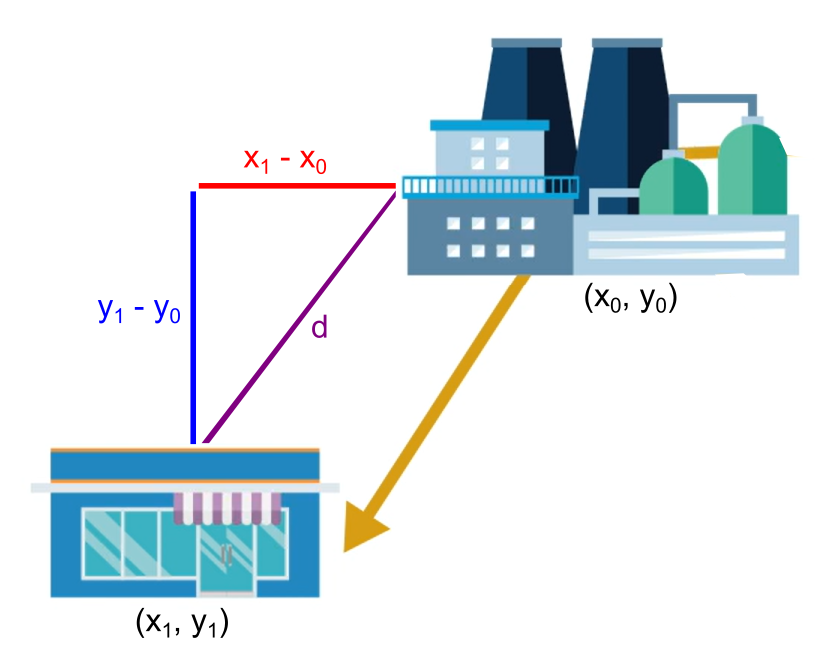


$$d=\sqrt{{\left(x_1 -x_0 \right)}^2 +{\left(y_1 -y_0 \right)}^2 }$$


$d_{\textrm{blue}}$ is distance between factory and blue store, $d_{\textrm{red}}$ is red store, and $d_{\textrm{yellow}}$ is yellow store. For simplicity sake, let's take the furthest distance.

Objective function: $d=\max \left(\;d_{\textrm{blue}} ,\;d_{\textrm{red}} ,\;d_{\textrm{yellow}} \;\right)$

### Variables

- Factory coordinate: $F_{\left(x,y\right)}$

### Constraints

- 
$$-10\le F_x \le 20$$


- 
$$-10\le F_y \le 20$$


## Solution

### Problem-Based Optimization

% Create problem
problem = optimproblem;

% Display problem information
show(problem);

### Define Objective Function


$$d=\sqrt{{\left(x_1 -x_0 \right)}^2 +{\left(y_1 -y_0 \right)}^2 }$$


$d_{\textrm{blue}}$ is distance between factory and blue store, $d_{\textrm{red}}$ is red store, and $d_{\textrm{yellow}}$ is yellow store. For simplicity sake, let's take the furthest distance.

Objective function: $d=\max \left(\;d_{\textrm{blue}} ,\;d_{\textrm{red}} ,\;d_{\textrm{yellow}} \;\right)$

function sigma_d = objective(factoryPosition, store1, store2, store3)
    
    d1 = pdist([store1; factoryPosition]);
    d2 = pdist([store2; factoryPosition]);
    d3 = pdist([store3; factoryPosition]);


  OptimizationProblem : 

  No problem defined.



    sigma_d = max([d1 d2 d3]);
end

### Solve with Optimization Task

% Create optimization variables
factoryPosition2 = optimvar("factoryPosition",1,2);

% Set initial starting point for the solver
initialPoint.factoryPosition = zeros(size(factoryPosition2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@objective,factoryPosition2,blueStore,...
    redStore,yellowStore);

% Define problem constraints
problem.Constraints.constraint1 = factoryPosition2(1) >= -10;
problem.Constraints.constraint2 = factoryPosition2(1) <= 20;
problem.Constraints.constraint3 = factoryPosition2(2) >= -10;
problem.Constraints.constraint4 = factoryPosition2(2) <= 20;

% Display problem information
show(problem);

% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);


% Display results
solution
reasonSolverStopped
objectiveValue

% Clear variables
clearvars factoryPosition2 initialPoint reasonSolverStopped objectiveValue


  OptimizationProblem : 

	Solve for:
       factoryPosition

	minimize :
       arg1

       where:

           arg1 = objective(factoryPosition, extraParams{1}, extraParams{2}, extraParams{3});

       extraParams


	subject to constraint1:
       factoryPosition(1) >= -10

	subject to constraint2:
       factoryPosition(1) <= 20

	subject to constraint3:
       factoryPosition(2) >= -10

	subject to constraint4:
       factoryPosition(2) <= 20
     



## Plot the Result

renderPlot(blueStore, redStore, yellowStore, solution.factoryPosition)

**Helper function**

function renderStoresPlot(blueStore,redStore,yellowStore)


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


    scatter(blueStore(1), blueStore(2), 'b*')
    hold on
    scatter(redStore(1), redStore(2), 'r*')

solution = struct with fields:
    factoryPosition: [6.3000 7.1000]

    scatter(yellowStore(1), yellowStore(2),'yellow','*')

reasonSolverStopped =     StepSizeBelowTolerance


    hold off

objectiveValue = 6.1400

    
    legend(["Blue store", "Red store", "Yellow store"])
    xlim([-10 20])
    ylim([-10 20])
end

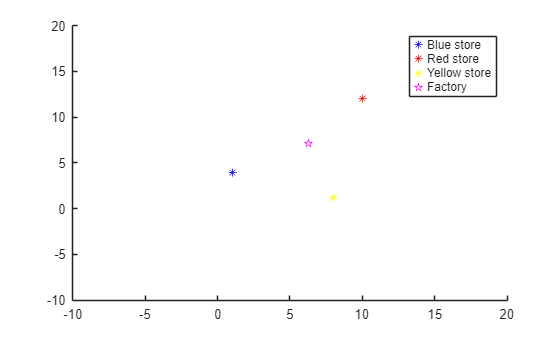

function renderPlot(blueStore,redStore,yellowStore,factory)

    scatter(blueStore(1), blueStore(2), 'b*')
    hold on
    scatter(redStore(1), redStore(2), 'r*')
    scatter(yellowStore(1), yellowStore(2),'yellow','*')
    scatter(factory(1), factory(2), 'magenta',"pentagram")
    hold off
    
    legend(["Blue store", "Red store", "Yellow store", "Factory"])
    xlim([-10 20])
    ylim([-10 20])
end